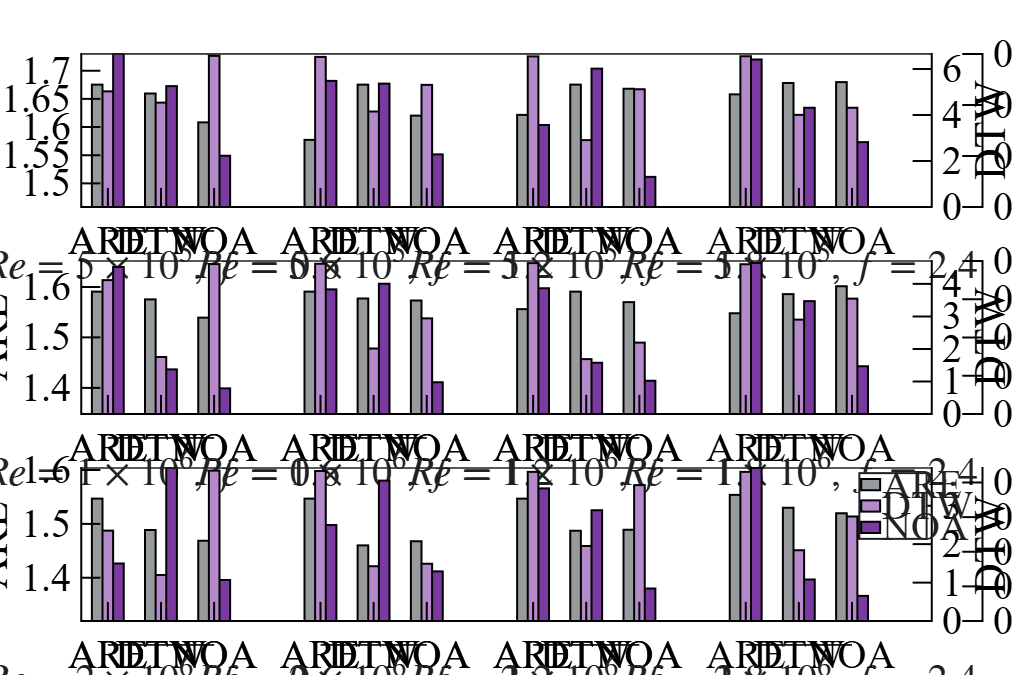

%% Main program:Iterate through subfolders and load selected.matfile
clear; clc; close all; warning off;
addpath(genpath(pwd));

% -------------------------- 1. Set root folder path --------------------------
mainFolder = 'compare_DTW_ARE_MSE_GZ_v2/';
folder     = {
    '-9.4±7_re5e5_0.6',...
    '-9.4±7_re5e5_1.2',...
    '-9.4±7_re5e5_1.8',...
    '-9.4±7_re5e5_2.4',... 
    '-9.4±7_re1e6_0.6',...
    '-9.4±7_re1e6_1.2',...
    '-9.4±7_re1e6_1.8',...
    '-9.4±7_re1e6_2.4',...
    '-9.4±7_re2e6_0.6',...
    '-9.4±7_re2e6_1.2',...
    '-9.4±7_re2e6_1.8',...            
    '-9.4±7_re2e6_2.4',...
    % '9.6±7_re5e5_0.6',...
    % '9.6±7_re5e5_1.2',...
    % '9.6±7_re5e5_1.8',...
    % '9.6±7_re5e5_2.4',...
    % '9.6±7_re1e6_0.6',...
    % '9.6±7_re1e6_1.2',...
    % '9.6±7_re1e6_1.8',...
    % '9.6±7_re1e6_2.4',...
    % '9.6±7_re2e6_0.6',... 
    % '9.6±7_re2e6_1.2',... 
    % '9.6±7_re2e6_1.8',... 
    % '9.6±7_re2e6_2.4',...
    };

% -------------------------- 3. Iterate through subfolders and load.matfile --------------------------
% Define files to search for.matfile-name list
targetMatFiles = {
    'data_collection_ARE.mat'
    'data_collection_DTW.mat'
    'data_collection_GZ.mat'
};
pattern = '^([^±]+)±.*?_re([^_]+)_(.+)$';
fontsize = 30;
line = 5;
mksize = 150;

fig1 = figure('Color','w','Position',[100 100 2400 2400]);
fig2 = figure('Color','w','Position',[100 100 2400 1600]);


Error_S = zeros(length(folder),4);
Error_M = zeros(length(folder),4);
Error_m = zeros(length(folder),4);
Error_cob = zeros(length(folder),4);
Error_ARE = zeros(length(folder),3);
Error_DTW = zeros(length(folder),3);
Error_GZ = zeros(length(folder),3);


% colors = [
%     248/255 172/255 140/255;     % Red(Category1)
%     154/255 201/255 219/255;     % Blue(Category2)
%     255/255 136/255 132/255;     % Green(Category3)
%     140/255 172/255 248/255;   % Orange(Category4)
% ];

colors = [
    161/255 169/255 208/255;     % Red(Category1)
    240/255 152/255 140/255;     % Blue(Category2)
    184/255 131/255 212/255;     % Green(Category3)
    158/255 158/255 158/255;   % Orange(Category4)
];

% colors = [
%     142/255 207/255 201/255;     % Red(Category1)
%     255/255 190/255 122/255;     % Blue(Category2)
%     250/255 127/255 111/255;     % Green(Category3)
%     130/255 176/255 210/255;   % Orange(Category4)
% ];

for i = 1:length(folder)
 % i = 1;
    subFolderName = folder(i);
    subFolderPath = fullfile(mainFolder, subFolderName);    
    validVarName = genvarname(subFolderName);
    currentFolderData = struct();
    
    %===================================Load data===================================
    for j = 1:length(targetMatFiles)
        matFilePath = fullfile(subFolderPath, targetMatFiles{j});

        if j == 1
            load(char(matFilePath))

            S_ARE = trapz(ARE_data(:,1) ,ARE_data(:,2));
            [max_ARE,i_ARE] = max(ARE_data(:,2));
            [min_ARE,j_are] = min(ARE_data(:,2));
            MAX_ARE = [max_ARE,ARE_data(i_ARE,1)];
            MIN_ARE = [min_ARE,ARE_data(j_are,1)];
        elseif j == 2
            load(char(matFilePath));

            S_DTW = trapz(DTW_data(:,1) ,DTW_data(:,2));
            [max_DTW,i_DTW] = max(DTW_data(:,2));
            [min_DTW,j_dtw] = min(DTW_data(:,2));
            MAX_DTW = [max_DTW,DTW_data(i_DTW,1)];
            MIN_DTW = [min_DTW,DTW_data(j_dtw,1)];
        elseif j == 3
            load(char(matFilePath));

            S_GZ = trapz(GZ_data(:,1) ,GZ_data(:,2));
            [max_GZ,i_GZ] = max(GZ_data(:,2));
            [min_GZ,j_gz] = min(GZ_data(:,2));
            MAX_GZ = [max_GZ,GZ_data(i_GZ,1)];
            MIN_GZ = [min_GZ,GZ_data(j_gz,1)];


            S_init= trapz(init_data(:,1) ,init_data(:,2));
            [max_init,i_init] = max(init_data(:,2));
            [min_init,j_init] = min(init_data(:,2));
            MAX_init = [max_init,init_data(i_init,1)];
            MIN_init = [min_init,init_data(j_init,1)];


            S_exp = trapz(exp_data(:,1) ,exp_data(:,2));

            [exp_up,exp_dw] = area_cover(ARE_data,DTW_data,GZ_data,init_data,exp_data);
        
            EXP_data = [exp_up
                        exp_dw];

            [max_EXP,i_EXP] = max(EXP_data(:,2));
            [min_EXP,j_exp] = min(EXP_data(:,2));
            MAX_EXP = [max_EXP,EXP_data(i_EXP,1)];
            MIN_EXP = [min_EXP,EXP_data(j_exp,1)];
        end
        
    end
    %===================================Compute error===================================
    Error_S(i,:) = new_areacover(ARE_data,DTW_data,GZ_data,init_data,exp_data);

    Error_M(i,:) = process_mat_data(MAX_ARE,MAX_DTW,MAX_GZ,MAX_init,MAX_EXP);

    Error_m(i,:) = process_mat_data(MIN_ARE,MIN_DTW,MIN_GZ,MIN_init,MIN_EXP);

    Error_cob(i,:) = (1-Error_S(i,:))*0.7 + Error_M(i,:)*0.15 + Error_m(i,:)*0.15;



    Error_ARE(i,:) = dataprocess_ARE(ARE_data,DTW_data,GZ_data,init_data,EXP_data);

    Error_DTW(i,:) = dataprocess_DTW(ARE_data,DTW_data,GZ_data,init_data,exp_data);
    
    Error_GZ(i,:) = dataprocess_GZ(ARE_data,DTW_data,GZ_data,init_data,EXP_data);



    %===================================Plot figures===================================
    ARE_data = [ARE_data(1:end,:)
                ARE_data(1,:)];

    DTW_data = [DTW_data(1:end,:)
                DTW_data(1,:)];

    GZ_data = [GZ_data(1:end,:)
                GZ_data(1,:)];

    init_data = [init_data(1:end,:)
                 init_data(1,:)];

    exp_data = [exp_data(1:end,:)
                exp_data(1,:)];

    match = regexp(folder{i}, pattern, 'tokens');
    meanangle = str2double(match{1}{1});
    Re        = str2double(match{1}{2});
    k         = str2double(match{1}{3});
    coeff = floor(log10(abs(Re)));
    base = Re / 10^coeff;
    %===================================Hysteresis-loop plot position===================================
    padding = 0.02;       
    h_spacing = 0.05;      
    v_spacing = 0.05;     
    n_cols = 3;            
    n_rows = 4;            
    
    subplot_width = (1 - 2*padding - (n_cols-1)*h_spacing) / n_cols;
    subplot_height = (1 - 2*padding - (n_rows-1)*v_spacing) / n_rows; 
    
    c = mod(i,3);
    r = fix(i/3);
    if c == 0
        c=3;
    end
    if i == 3 || i == 6 || i == 9 || i ==12
        r = r-1;
    end

    left = padding + (c-1)*(subplot_width + h_spacing);
    bottom = padding + (3-r)*(subplot_height + v_spacing);
    pos = [left, bottom, subplot_width, subplot_height];
    %===================================Bar-chart position===================================
    tick = 0.08;
    v = 0.08;
    pos1 = [tick, tick + 2*((1-2*tick-2*v)/3 + v),(1-2*tick),(1-2*tick-2*v)/3];
    pos2 = [tick, tick + ((1-2*tick-2*v)/3 + v)  ,(1-2*tick),(1-2*tick-2*v)/3];
    pos3 = [tick, tick                           ,(1-2*tick),(1-2*tick-2*v)/3];


    %===================================Bar chart===================================

    figure(fig2);
    if i>=1 && i<=4
        pos_e = pos1;
    elseif i>4 && i<=8
        pos_e = pos2;
    elseif i>8 && i<=12
        pos_e = pos3;
    end
     
    x = [0.5 1.5 2.5
        4.5 5.5 6.5 
        8.5 9.5 10.5 
        12.5 13.5 14.5];

    if i == 4 || i == 8 || i == 12
        p = 4;
    else
        p = mod(i,4);
    end
    y1 = Error_ARE(i,:)';
    y2 = Error_DTW(i,:)';
    y3 = Error_GZ(i,:)';
    baroffset = 0.2;
    figoffset = 0.03;
    offset = 0.05;
    color1 = [151/255 155/255 157/255];
    color2 = [181/255 138/255 202/255];
    color3 = [122/255 58/255 160/255];
    categories = {'ARE', 'DTW', 'NOA'};
    %===========================Figure1===========================
    ax(5) = axes('Parent',fig2,'Position',pos_e);
    set(ax(5),'YTick',[],'XTick',[],'LineWidth', 1.2,'Color','none','box','on');
    ax(1) = axes('Parent',fig2,'Position',pos_e);
    b1 = bar(x(p,:)-baroffset, y1, 0.2, 'FaceColor',color1,'EdgeColor','k','LineWidth',1.5);
    ax(1).YColor = color1;
    lg1 = legend('ARE');
    lg1.Visible = "off";

    if i == 4 || i == 8 || i == 12
        set(ax(1),'YAxisLocation','left','box','off', ...
            'Color','none','YColor','k','XColor','k',...
            'ylim',[min(y1)-0.2 max(y1)+0.05],'xlim',[0 16], ...
            'xtick',[],'xticklabel',categories,...
            'LineWidth', 1.5,'FontName','Times New Roman','Fontsize',fontsize);
        ax(1).YLabel.String = 'ARE';
    else
        set(ax(1),'YAxisLocation','left','box','off', ...
            'Color','none','YColor','none','XColor','k',...
            'ylim',[max(y1)-0.2 max(y1)+0.05],'xlim',[0 16], ...
            'xtick',x(p,:),'xticklabel',categories, ...
            'LineWidth', 1.5,'FontName','Times New Roman','Fontsize',fontsize);
    end
    %===========================Figure2===========================
    ax(2) = axes('Parent',fig2,'Position',pos_e);
    b2 = bar(x(p,:), y2, 0.2, 'FaceColor',color2,'EdgeColor','k','LineWidth',1.5);
    lg2 = legend('DTW');
    lg2.Visible = "off";

    if i == 4 || i == 8 || i == 12
    set(ax(2),'YAxisLocation','right','box','off', ...
        'Color','none','YColor','k','XColor','k',...
        'xlim',get(ax(1),'xlim'),'ylim',[0 max(y2)+0.1], ...
        'xtick',[],'xticklabel',categories, ...
        'LineWidth', 1.5,'FontName','Times New Roman','Fontsize',fontsize);
        ax(2).YLabel.String = 'DTW';
    else
        set(ax(2),'YAxisLocation','right','box','off', ...
            'Color','none','YColor','none','XColor','none',...
            'xlim',get(ax(1),'xlim'),'ylim',[0 max(y2)+0.1], ...
            'xtick',x(p,:),'xticklabel',categories, ...
            'LineWidth', 1.5,'FontName','Times New Roman','Fontsize',fontsize);
    end
    % Determine the position of the third axes
    pos1 = ax(1).Position;
    pos4 = [pos1(1) pos1(2) pos1(3)+offset pos1(4)];
    %===========================Figure3===========================
    ax(3) = axes('Parent',fig2,'Position',pos_e);
    b3 = bar(x(p,:)+baroffset, y3, 0.2, 'FaceColor',color3,'EdgeColor','k','LineWidth',1.5);
    set(ax(3),'box','off','yaxislocation','right',...
       'Color','none','XColor','none','YColor','none','XColor','k',...   
       'xtick',x(p,:),'xticklabel',categories,'xlim',get(ax(1),'xlim'), ...
       'LineWidth', 1.5,'FontName','Times New Roman','Fontsize',fontsize);
    lg3 = legend('NOA');
    lg3.Visible = "off";

    if i == 4 || i == 8 || i == 12
        ax(4) = axes('Parent',fig2,'Position',pos4);
        plot(0,0);
        set(ax(4),'yaxislocation','right','box','off',...
           'Color','none','XColor','none','YColor','k',...   
           'xlim',get(ax(1),'xlim'),'ylim',get(ax(3),'ylim'), ...
           'xtick',[],'xticklabel',categories, ...
           'LineWidth', 1.5,'FontName','Times New Roman','Fontsize',fontsize);
        ax(4).YLabel.String = 'NOA';
    end
    if i == 4 || i == 8 || i == 12 

        ax_line = axes('Parent',fig2,'Position',[pos_e(1),pos_e(2)-0.158,pos_e(3),pos_e(4)], ...
                       'Color','none','XColor','none','YColor','none', ...
                       'XTick',[],'YTick',[],'Box','off');
        
        hold(ax_line,'on');
        
        yl = ax(1).YLim;
        yline = yl(1) - 0.05*(yl(2)-yl(1));  % distance from bottom 5%
        
        ff = [0.6 1.2 1.8 2.4];
        group_ranges = [0.5 2.5; 4.5 6.5; 8.5 10.5; 12.5 14.5]; 
        for k = 1:size(group_ranges,1)
            name = sprintf('$Re=%.0f \\times 10^{%d}$, $f=%.1f$',base, coeff, ff(k));
            draw_group(ax_line, group_ranges(k,:), -0.15, name, -0.22);
            ax_line.XLim = ax(1).XLim;
        end
    end

    if i == 12
        lg = legend(ax(3), [b1 b2 b3], {'ARE','DTW','NOA'}, ...
                    'Location','northeast', ...
                    'Box','on', ...
                    'FontName','Times New Roman', ...
                    'FontSize', fontsize);
    end


end

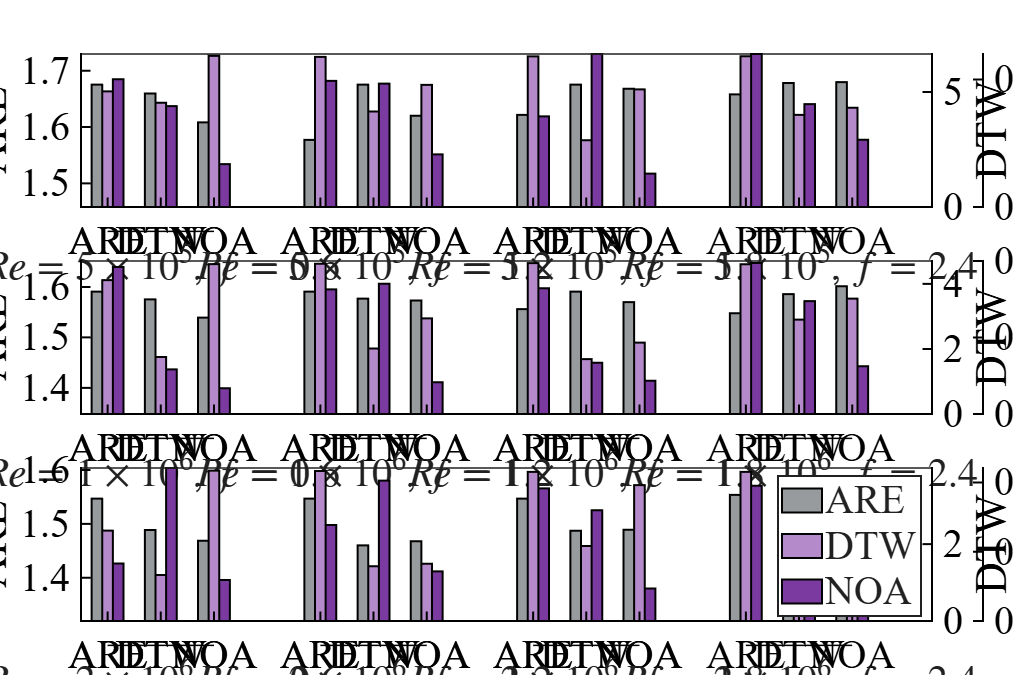

figure(fig2);
% saveas(fig4, ['error_m_compare','.png']);
exportgraphics(fig2,'error_cob_compare1.pdf','ContentType', 'vector')